grid = gen_grid();
N = 2000;
seed = 100;
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,seed,"Cirkel");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
networks = metropolis_hasting(N, 0.4, 10, data);

seed = 390

burned = 0.0382

iterations = 0.0359

resultNetworks = cell(1,100);
indexes = randperm(N,100);
for ind = 1:length(indexes) 
     resultNetworks{1,ind} = networks{1,indexes(ind)}; 
end

% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

class_vec = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, resultNetworks);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    uncert_color = [uncert_color; (base + r + g)];

end

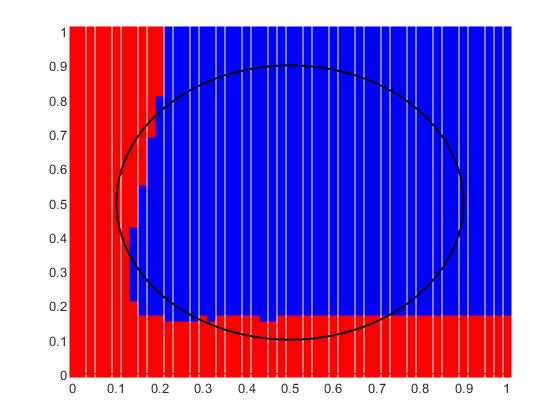

grid = gen_grid();
corClass = correct_classify_circle(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,resultNetworks);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "A"
                cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "B"
                cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;


    
figure
hold on
axis([0 1 0 1])
scatter(XA,YA,80,'blue','filled','s')
scatter(XB,YB,80,'red','filled','s')
plot(xunit,yunit,'black','LineWidth',1.5);
hold off


percentage_correct = (cor_counter/length(grid)) * 100

percentage_correct = 73.4717

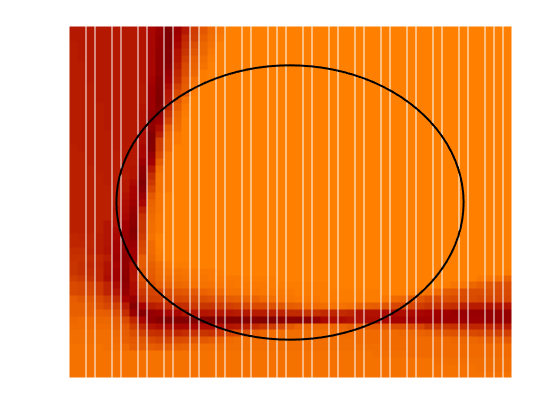


% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,uncert_color,'filled','s')

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;
plot(xunit,yunit,'black','LineWidth',1.5);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off

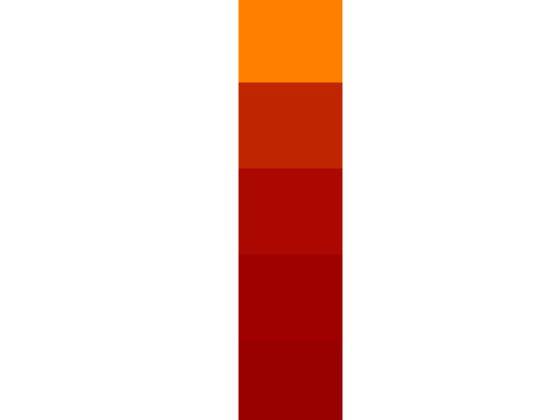

legend_col = [];
for i = 5:-1:1 
    u = 1/i; 
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    legend_col = [legend_col; (base + r + g)];
end

scatter([1 1 1 1 1], [1:5],10000,legend_col,'filled','s')

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')